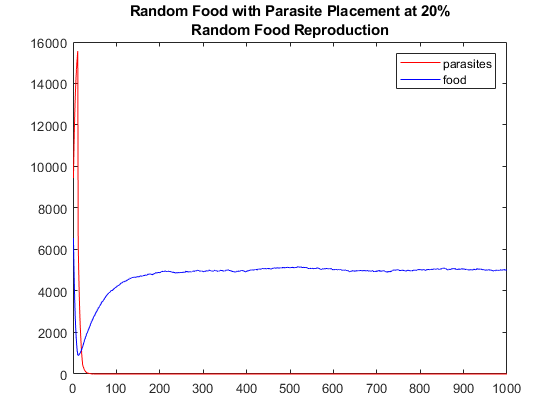

density = 0.2;
[domain, food, parasites] = initial_random_position(density);

iterations = 1000;
f1 = 10; % parasites' age [0 15]
f2 = 0.02; % food death rate
f3 = 100; % food respawn
video = false;

[p, f] = stimulate(domain, parasites, food, iterations, f1,f2, f3, video);

%% Results
t = 1:1:size(p, 2);
figure;
plot(t, p, 'r');
hold on
plot(t, f, 'b');
legend('parasites', 'food');
title({'Random Food with Parasite Placement at 20%'; 'Random Food Reproduction'});

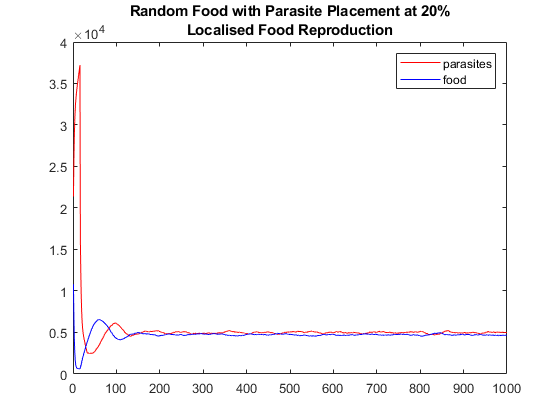

density = 0.4;
[domain, food, parasites] = initial_random_position(density);

iterations = 1000;
f1 = 15; % parasites' age [0 15]
f2 = 0.02; % food death rate
f3 = 400; % food respawn
video = false;

[p, f] = stimulate(domain, parasites, food, iterations, f1,f2, f3, video);

%% Results
t = 1:1:size(p, 2);
figure;
plot(t, p, 'r');
hold on
plot(t, f, 'b');
legend('parasites', 'food');
title({'Random Food with Parasite Placement at 20%'; 'Random Food Reproduction'});

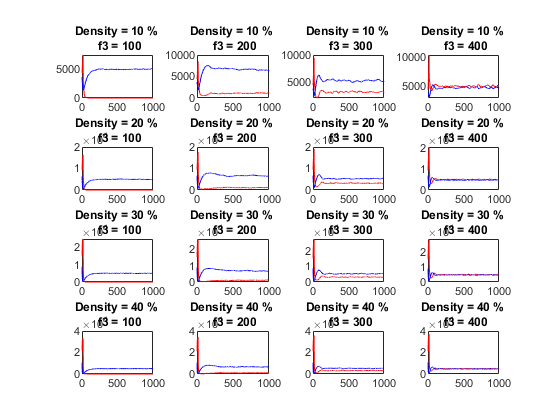

density = [0.1 0.2 0.3 0.4];
iterations = 1000;
f1 = 15; 
f2 = 0.02;
f3 = [100 200 300 400];
video = false;
t = 1:1:iterations;

figure_index = 0;

for i=1:4
    for j = 1:4
        figure_index = figure_index + 1;
        [domain, food, parasites] = initial_random_position(density(i));
        [p, f] = stimulate(domain, parasites, food, iterations, f1,f2, f3(j), video);
        
        subplot(4, 4, figure_index);
        plot(t, p, 'r', t, f, 'b');        
        title(sprintf("Density = %d %% \n f3 = %d", density(i) * 100, f3(j)));
        
    end
end